clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
% DHparameter=[0 0 0.04 0;
%              0.12 pi/2 0 13*pi/30;
%              0.194 0 0 -23*pi/30;
%              0 -pi/2 0.176 0;
%              0 pi/2 0 pi/2;
%              0 pi/2 0 0]

% DHparameter=[0 0 4 0;
%              12 pi/2 0 0;
%              19.4 0 0 0;
%              0 -pi/2 17.6 0;
%              0 pi/2 0 0;
%              0 pi/2 0 0]
DHparameter=[0 pi/2 0.04 0;
             0.12 0 0 13*pi/30+pi/2;
             0.194 -pi/2 0 -23*pi/30+pi/2;
             0 0 0.176 0;
             0 pi/2 0 pi/2;
             0 0 0 0]

DHparameter =          0    1.5708    0.0400         0
    0.1200         0         0    2.9322
    0.1940   -1.5708         0   -0.8378
         0         0    0.1760         0
         0    1.5708         0    1.5708
         0         0         0         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",6,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
% joint1.PositionLimits = [-pi/3 pi/3];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
joint2.HomePosition = 13*pi/30+pi/2;
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];
body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [0 0.1];
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [0 0.1];
body6.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------


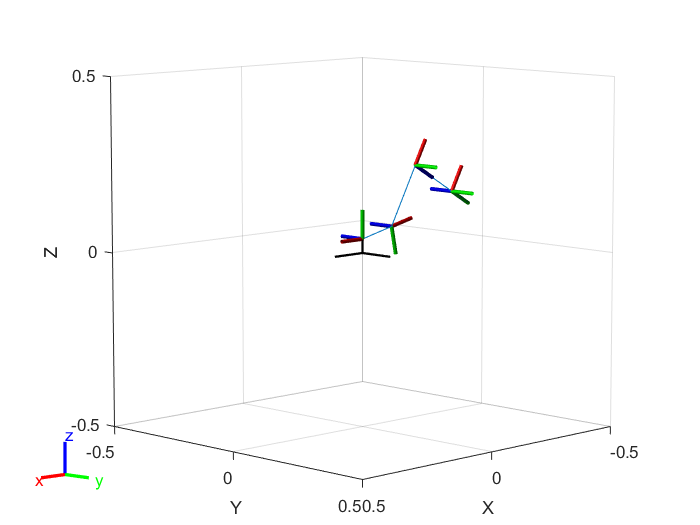


show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

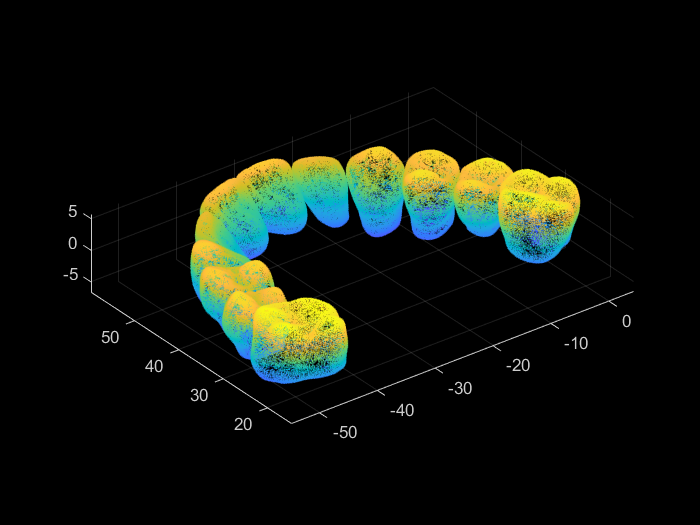

% Read and plot complete denture
stlData = stlread('stl/1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

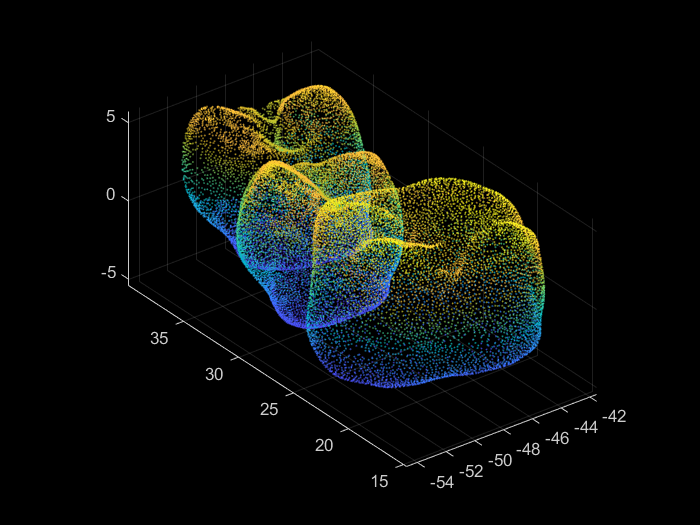


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

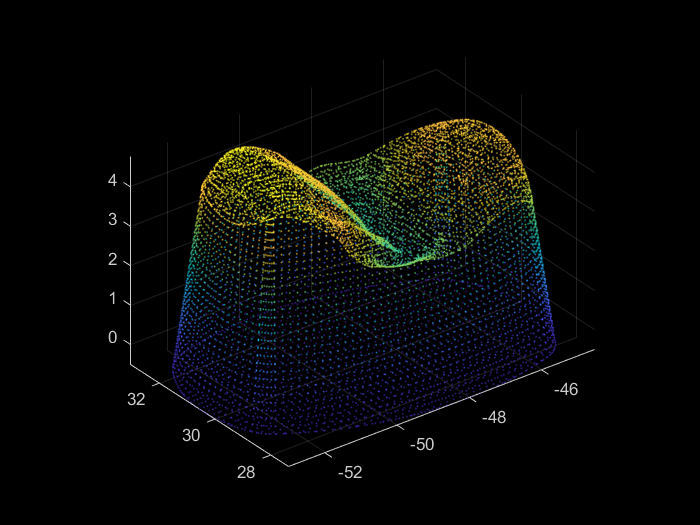


% Import and plot final model individually
stlData_fin = stlread("stl/1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

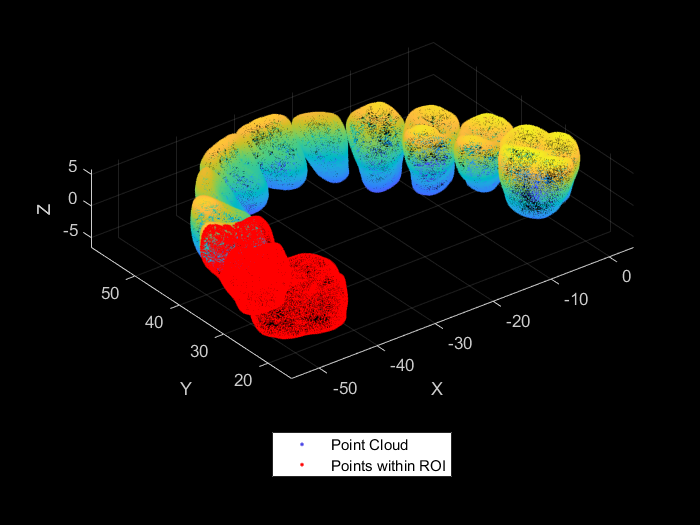


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

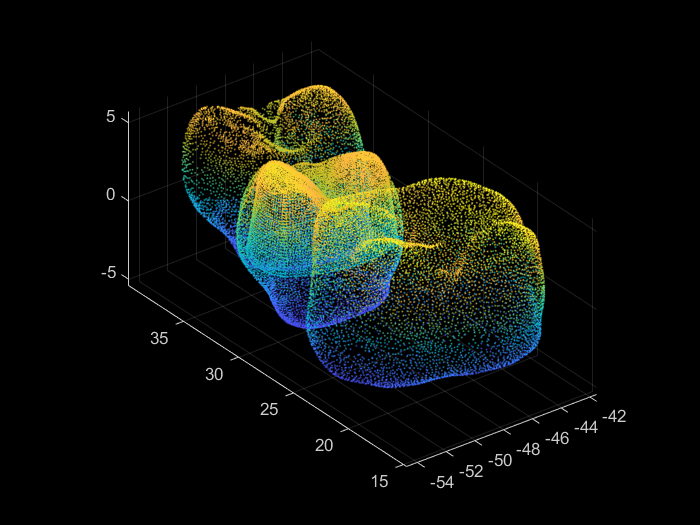


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

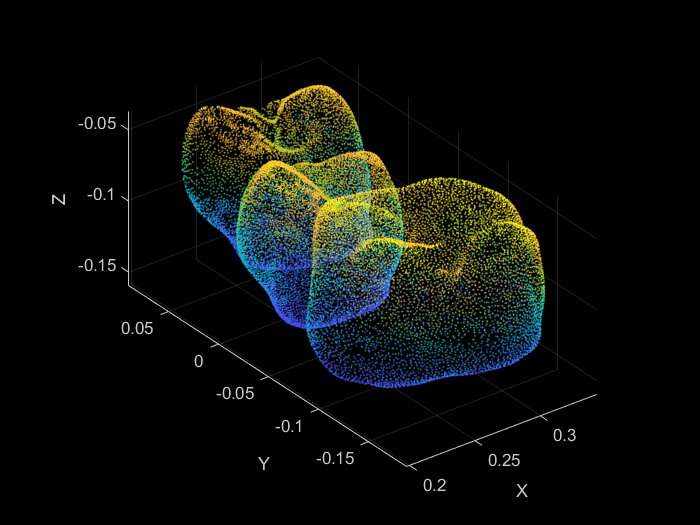


%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.8 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

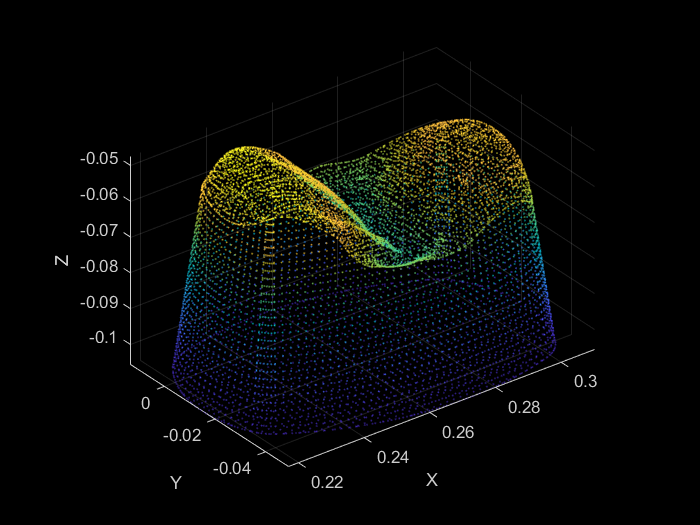

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.005

r = 0.0050

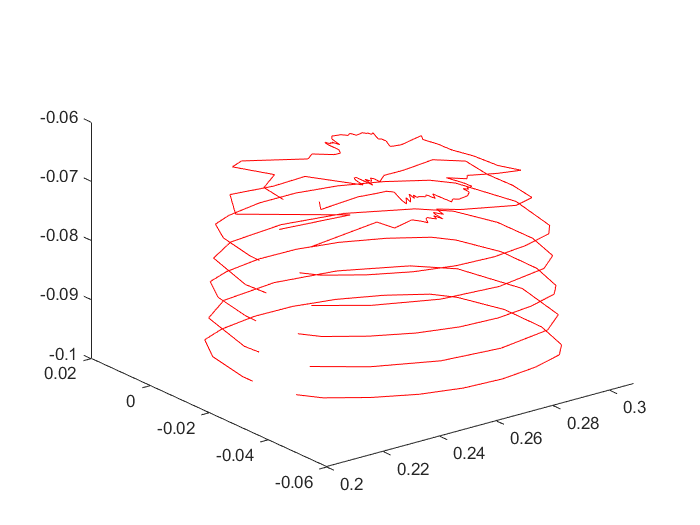

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],20);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

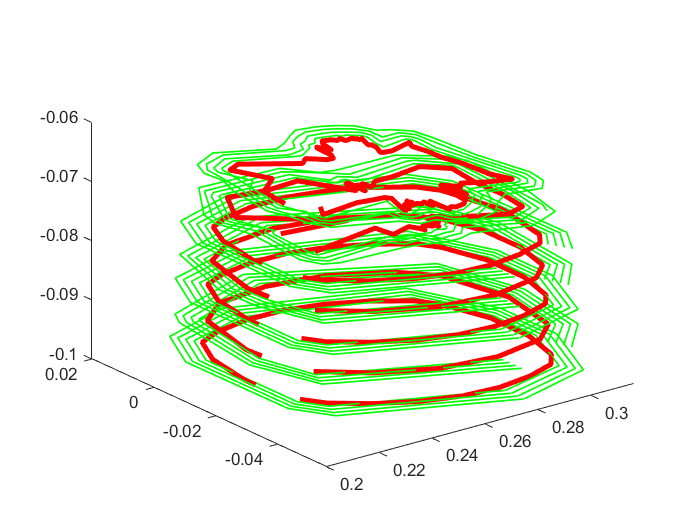

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,20);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {22×3 double}    {15×3 double}    {22×3 double}    {16×3 double}    {21×3 double}    {41×3 double}    {82×3 double}
    {11×3 double}    {10×3 double}    {11×3 double}    {10×3 double}    {10×3 double}    {37×3 double}    {58×3 double}
    {11×3 double}    {10×3 double}    {11×3 double}    {10×3 double}    {10×3 double}    {30×3 double}    {46×3 double}
    {11×3 double}    {10×3 double}    {11×3 double}    {10×3 double}    {10×3 double}    {25×3 double}    {38×3 double}
    {11×3 double}    {10×3 double}    {11×3 double}    {10×3 double}    {10×3 double}    {23×3 double}    {34×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

**Save all quarters in arrays**

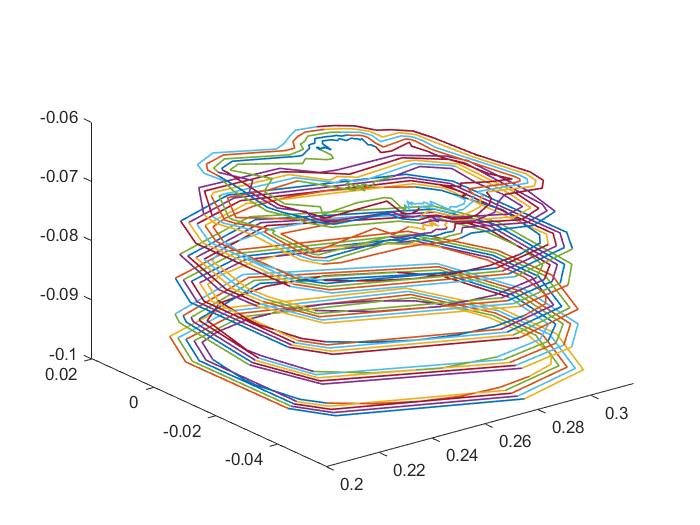

curve1 = allPoints{5,1};
appendAllPoints = [];
figure
for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

% Show a single curve.
% figure
% [q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);

% q2 is front
% q1 is right
% q3 is left
% q4 is back

**Splitting Geometry and Forming into Trajectory**

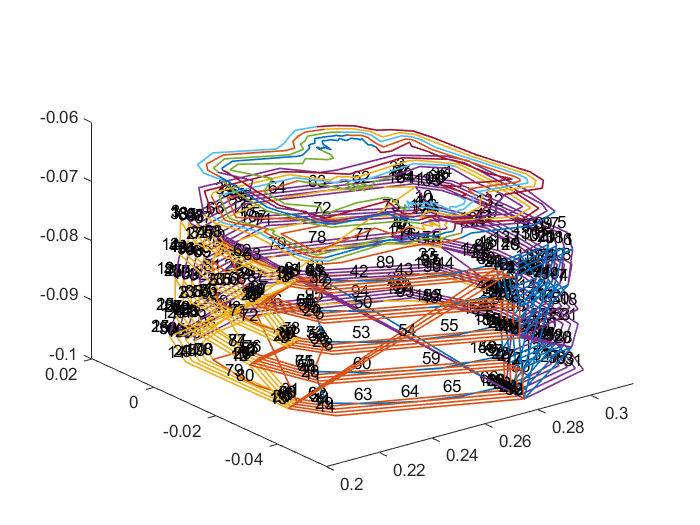

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);
plotQuarter(q1_traj_arr);
plotQuarter(q2_traj_arr);
plotQuarter(q3_traj_arr);
plotQuarter(q4_traj_arr);
hold off

**Calculate IK for Trajectories**

ik = inverseKinematics("RigidBodyTree",dental);
weights = [0 0 0 1 1 1];
q0 = homeConfiguration(dental);
qinitial = q0;
ik.SolverParameters.MaxIterations = 45000;
% ik.SolverParameters.MaxTime = 1000
for i = 1:length(q1_traj_arr)
%     point = q1_traj_arr(i,:);
    pose = trvec2tform(q1_traj_arr(i,:)); %*axang2tform([1 0 0 pi]);
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q1_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 6624
    NumRandomRestarts: 1
        PoseErrorNorm: 7.0212e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4548e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3473e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5308e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3531e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7868e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1137e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5818e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3904e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0027e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2238e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7034e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6360e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0359e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2832e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5251e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0354e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0094e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5830e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6578e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5045e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8619e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9758e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7268e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2297e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1496e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9659e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4713e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1358e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2177e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8316e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9443e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 12
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5427e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2938e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.2111e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6504e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9050e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9537e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8388e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6708e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7760e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3004e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5690e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6955e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4628e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7627e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6790e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0603e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5043e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3246e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4725e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0725e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0732e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4951e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3091e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3522e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8208e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5732e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3435e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0534e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8760e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4847e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1884e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4548e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5939e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1676e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0233e-09
             ExitFlag: 1
               Status: 'success'


q1_traj_arr(5,:)

ans =     0.2747   -0.0546   -0.0875


getTransform(dental,q1_config(:,5),'Body6')

ans =    -0.9086    0.3010    0.2895    0.2747
   -0.3781   -0.2987   -0.8762   -0.0546
   -0.1772   -0.9056    0.3852   -0.0875
         0         0         0    1.0000


qinitial = q0;
for i = 1:length(q2_traj_arr)
%     pose = trvec2tform(q2_traj_arr(i,:))*axang2tform([1 0 0 pi]);
%     q2_config(:,i) = ik("Body6",pose,weights,dental.homeConfiguration);
    pose = trvec2tform(q2_traj_arr(i,:)); %*axang2tform([1 0 0 pi]);
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q2_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 121
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3417e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7066e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2193e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0224e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6728e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8705e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1593e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4747e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2089e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7620e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0936e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0619e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7161e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8173e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3751e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5966e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0502e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1704e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4560e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4395e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2530e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1836e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0699e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9546e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6462e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0088e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0077e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7402e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9873e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9053e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6555e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1624e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3612e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7711e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9788e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3853e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2075e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7935e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9454e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5385e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8237e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0088e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7633e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3862e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6782e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7077e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2081e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8008e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1639e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2810e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0659e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2308e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7875e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1808e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4386e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0700e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1788e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7853e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7564e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7113e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 21
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9632e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6933e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6663e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7439e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3748e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3772e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4024e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3108e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 39
    NumRandomRestarts: 1
        PoseErrorNorm: 8.3823e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 62
    NumRandomRestarts: 2
        PoseErrorNorm: 9.7602e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8012e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9870e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6316e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2013e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2481e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2321e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7490e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5512e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9071e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0240e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1818e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0839e-08
             ExitFlag: 1
               Status: 'success'


qinitial = q0;
for i = 1:length(q3_traj_arr)
%     pose = trvec2tform(q3_traj_arr(i,:))*axang2tform([1 0 0 pi]);
%     q3_config(:,i) = ik("Body6",pose,weights,dental.homeConfiguration);
    pose = trvec2tform(q3_traj_arr(i,:)); %*axang2tform([1 0 0 pi]);
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q3_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 849
    NumRandomRestarts: 1
        PoseErrorNorm: 3.5219e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8828e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4826e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2034e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3588e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3084e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7832e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 9.5167e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3269e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1629e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3511e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3193e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4225e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2551e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3436e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3124e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8832e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5691e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9976e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9734e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4342e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6872e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7124e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9466e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0894e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5470e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9979e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5076e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7669e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0608e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0308e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8822e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6651e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9287e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8463e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0917e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5947e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0500e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0617e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0603e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5062e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8385e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6322e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8620e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2007e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6827e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1535e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4128e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0062e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5770e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6757e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5058e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2656e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5692e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9846e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5442e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2108e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7719e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1986e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1185e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0832e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3048e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3759e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4430e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0947e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0733e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2243e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0744e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7486e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6031e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3681e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2214e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1096e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0004e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6257e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1850e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3514e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5947e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5646e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.8697e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2336e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2652e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9357e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9066e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4256e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6616e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7783e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6402e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3360e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0313e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.9786e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3407e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0038e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7264e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7246e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5885e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7659e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3122e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5234e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5049e-09
             ExitFlag: 1
               Status: 'success'


qinitial = q0;
for i = 1:length(q4_traj_arr)
%     pose = trvec2tform(q4_traj_arr(i,:))*axang2tform([1 0 0 pi]);
%     q4_config(:,i) = ik("Body6",pose,weights,dental.homeConfiguration);
    pose = trvec2tform(q4_traj_arr(i,:)); %*axang2tform([1 0 0 pi]);
    [qsol, solinfo] = ik("Body6",pose,weights,qinitial);
    q4_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 5653
    NumRandomRestarts: 3
        PoseErrorNorm: 4.9237e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6997e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8130e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7454e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9544e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4594e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9532e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6801e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7102e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7352e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8824e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5706e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4160e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 12
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3266e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1371e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9845e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5258e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.1500e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2287e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3764e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0163e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3558e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1243e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8668e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9968e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4088e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2601e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3524e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1975e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6846e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0662e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7150e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6369e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1956e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7517e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6199e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1607e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9955e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5813e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1599e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2922e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2178e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8700e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9435e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3564e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 12
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7608e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4728e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3161e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2454e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6669e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1541e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4408e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2003e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9197e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8904e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5818e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0743e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1281e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1709e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1046e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3053e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2307e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7809e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7539e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3702e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0620e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3686e-11
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3274e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0750e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4077e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5644e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4649e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.8097e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0332e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7779e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9081e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2950e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2314e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7687e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2575e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6121e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5477e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1151e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1191e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5663e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4329e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2463e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9323e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6916e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9801e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 12
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4536e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6599e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8011e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4864e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5720e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6693e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6715e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5405e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2749e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7796e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 19
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7236e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0905e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6201e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6808e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4248e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8556e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5890e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5487e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2326e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2555e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5179e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5576e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4882e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7215e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0756e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9839e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2813e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7310e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0712e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1553e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 18
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4775e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9662e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 11
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0773e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5264e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2340e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0352e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9105e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7144e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9048e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8885e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2489e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7281e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3783e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5241e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0338e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9671e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0964e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0502e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9345e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2399e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7245e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3587e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3905e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2326e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0862e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2198e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2101e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8656e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7375e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 17
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5133e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5953e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7119e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 14
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5621e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 15
    NumRandomRestarts: 0
        PoseErrorNorm: 5.0278e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 16
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0009e-08
             ExitFlag: 1
               Status: 'success'


save q_configs q1_config q2_config q3_config q4_config;
q_config = matfile('q_configs.mat');
q1_config = q_config.q1_config;
q1_config = trapveltraj(q1_config,length(q1_config(1,:)),"EndTime",2);


% q2_config = q_config.q2_config;
% q2_config = trapveltraj(q2_config,length(q2_config(1,:)),"EndTime",2);
% q3_config = q_config.q3_config;
% q3_config = trapveltraj(q3_config,length(q3_config(1,:)),"EndTime",2);
% q4_config = q_config.q4_config;
% q4_config = trapveltraj(q4_config,length(q4_config(1,:)),"EndTime",2);

%Combine and add home config between
homeConfig = findHomeConfig(ptCloud_fin);
pose = trvec2tform(homeConfig) %*axang2tform([1 0 0 pi]);

pose =     1.0000         0         0    0.2635
         0    1.0000         0   -0.0178
         0         0    1.0000         0
         0         0         0    1.0000


home = ik("Body6",pose,weights,dental.homeConfiguration);
%Need to get traj between last config of each q and home, then add these
%trajs to q_tot
t = 20;
q_1tohome = trapveltraj([q1_config(:,length(q1_config(1,:))),home],t,"EndTime",2);
% q_hometo2 = trapveltraj([home,q2_config(:,1)],t,"EndTime",2);
% q_2tohome = trapveltraj([q2_config(:,length(q2_config(1,:))),home],t,"EndTime",2);
% q_hometo3 = trapveltraj([home,q3_config(:,1)],t,"EndTime",2);
% q_3tohome = trapveltraj([q3_config(:,length(q3_config(1,:))),home],t,"EndTime",2);
% q_hometo4 = trapveltraj([home,q4_config(:,1)],t,"EndTime",2);

% q_tot = [q1_config q_1tohome q_hometo2 q2_config q_2tohome q_hometo3 q3_config q_3tohome q_hometo4 q4_config];
q_tot = [q1_config q2_config q3_config q4_config];

## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
% ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
% startPose = trvec2tform([0.220641 -0.0406355 -0.0975])*axang2tform([1 0 0 pi]);
% endPose = trvec2tform([homeConfig(:,1) homeConfig(:,2) homeConfig(:,3)])*axang2tform([1 0 0 pi]);
% 
robotCollision = isInCollision(q_tot, MSH, dental)

robotCollision = logical
   0


% 
% startPose1 = trvec2tform([homeConfig(:,1) homeConfig(:,2) homeConfig(:,3)])*axang2tform([1 0 0 pi]);
% endPose1 = trvec2tform([0.301326 0.00537663 -0.0775])*axang2tform([1 0 0 pi]); 
% robotCollision1 = isInCollision(startPose1, endPose1, MSH, dental)

**Calculate and Plot Closest points**

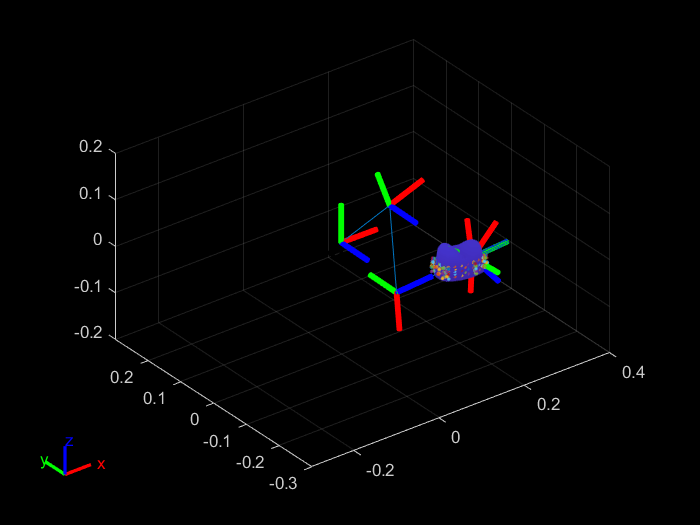

[minimum,ind,ee_arr] = min2pts(dental,q_tot,ptCloud_fin);

figure
pcshow(ptCloud_fin)
hold on
show(dental,home,'PreservePlot',false);
hold on
% plotQuarter(q1_traj_arr); hold on
% plotQuarter(q2_traj_arr); hold on
% plotQuarter(q3_traj_arr); hold on
% plotQuarter(q4_traj_arr); hold on
plotClosest(dental,q_tot,ee_arr,ind,ptCloud_fin);

% plotClosest(dental,q2_config,ee_arr,ind,ptCloud_fin);
% plotClosest(dental,q3_config,ee_arr,ind,ptCloud_fin);


## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
    curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body6','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 20;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis([-0.3 0.4 -0.3 0.3 -0.2 0.2])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
%         line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
        plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
    
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = 0;
    homeConfig = [x y z];
end

### `Check if path in collision or not`

function isTrajectoryInCollision = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
    rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
end